Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Potential of an off-center beam in a round beam pipe (Section 7.2)

Volker Ziemann, 211124, CC-BY-SA-4.0

In this example, we calculate the joint potential from an off-center beam in a round beam pipe and an image charge placed outside the beam pipe and vary the position of the image charge to make the beam pipe an equipotential surface.

Herewe place the beam at $d_1=R/3$ off-center in a beam pipe with radius $R=1$ and we place an image charge at $d_2$ as shown in Figure 7.3, and use the slider to vary its position $d_2$.

clear; 
d1=1/3;  % off-center position of the beam
d2=4.4   % Slider to set the position of the image charge

d2 = 4.4000

The potential $V(x,y)$of a point charge is proportional to$V(x,y)\propto \log(|z|)/2\pi i$with $z=x+iy$. We therefore define an anonymous function $V(x,y)$ to return the potential at the point $x,y$ from the two charges and plot it on a circle with radius $R=1$, the beam pipe.

V=@(x,y)0.5*log((x-d1).^2+y.^2)-0.5*log((x-d2).^2+y.^2); % potential
phi=(0:2:360)*pi/180; 
plot(phi,V(cos(phi),sin(phi)),'k');

The task at hand is now to find the position $d_2$ of the image charge that makes the beam pipe an equipotential surface. We therefore calculate the rms-variation of the potential and display it on the top of the figure. The rest of the code simply annotates the figure.

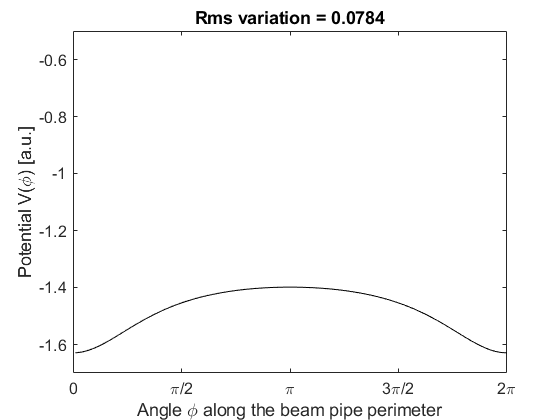

r=std(V(cos(phi),sin(phi)));
xlabel('Angle \phi along the beam pipe perimeter')
ylabel('Potential V(\phi)')
title(['Rms variation = ',num2str(r,'%6.4f')])
xlim([0,2*pi]); ylim([-1.7 -0.5])
set(gca,'xtick',[0,pi/2,pi,3*pi/2,2*pi],'fontsize',12, ...
    'xticklabels',{'0','\pi/2','\pi','3\pi/2','2\pi'})

Compare the value of $d_2$ that you find from minimizing the rms-variation of the potential to the one derived in Section 7.2! 